### **TASK 2A**


% Task 2A

% clear

% Below, values of pressure and temperature (in Kelvin so that they don't
% need to be converted when input into an equation) from question 2A are
% defined. (The value for 0K (Kelvin) or absolute zero is taken as -273.15
% degrees celcius).
P = 101.325*10^3

P = 101325

T_K = [10:1:80]'+273.15 

T_K =   283.1500
  284.1500
  285.1500
  286.1500
  287.1500
  288.1500
  289.1500
  290.1500
  291.1500
  292.1500



% Calling the Task 2 Function File Above to Find Values of H_21, P_v1, phi_1
% & phi_2:
[H_21, P_v1, phi_1, phi_2] = Task2_Function_Values(P, T_K)

Tc =   304.1800  647.0960


Pc =      7380000    22064000


wh_af =     0.2250    0.3480


h1 = -6.8346

h2 = 12817

h3 = -3766800

h4 = 299700000

a1 = -7.8595

a2 = 1.8441

a3 = -11.7866

a4 = 22.6807

a5 = -15.9619

a6 = 1.8012

R = 8.3140

a =     0.3962    0.5998


a_star =     0.4162    1.0097
    0.4153    1.0081
    0.4143    1.0065
    0.4133    1.0049
    0.4123    1.0033
    0.4114    1.0018
    0.4104    1.0002
    0.4095    0.9986
    0.4085    0.9970
    0.4075    0.9955


b = 1.0e-04 *

    0.2666    0.1897


A =     0.0076    0.0185
    0.0075    0.0183
    0.0075    0.0181
    0.0074    0.0180
    0.0073    0.0178
    0.0073    0.0177
    0.0072    0.0175
    0.0071    0.0174
    0.0071    0.0172
    0.0070    0.0171


B =     0.0011    0.0008
    0.0011    0.0008
    0.0011    0.0008
    0.0011    0.0008
    0.0011    0.0008
    0.0011    0.0008
    0.0011    0.0008
    0.0011    0.0008
    0.0011    0.0008
    0.0011    0.0008


H_21 = 1.0e+08 *

    1.0461
    1.0800
    1.1146
    1.1498
    1.1856
    1.2221
    1.2592
    1.2969
    1.3352
    1.3741


P_v1 = 1.0e+04 *

    0.1228
    0.1313
    0.1403
    0.1498
    0.1599
    0.1706
    0.1819
    0.1938
    0.2065
    0.2198


phi_1 =   102.7474
   95.8492
   89.4641
   83.5504
   78.0702
   72.9889
   68.2747
   63.8988
   59.8347
   56.0579


phi_2 =     0.9935
    0.9936
    0.9937
    0.9937
    0.9938
    0.9939
    0.9939
    0.9940
    0.9941
    0.9941


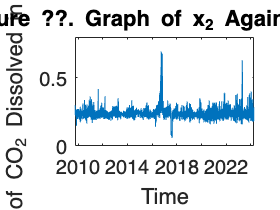


% Note that pressure is constant in the graphs below therefore the values
% under consideration fluctuate with respect to temperature exclusively.

% Plotting the Figures in a 4x4 Grid

% H_21
figure
subplot(2,2,1)
plot(T_K-273.15,H_21,LineWidth=1)
% Use of xlim better fits the line graph to the axes (so there is no
% discrepancy between the start of the graph and the start of the x axes).
% Additionally, temperature is converted from kelvin to degrees celcius as 
% the question suggests. 
xlim([T_K(1)-273.15,T_K(end)-273.15])
xlabel("Temperature ( ^oC )")
ylabel("Temperature Dependant Henry's Constant H_2_1 (ND)")
title("Figure ??. Graph of H_2_1 Against Temperature")

% P_v1
hold on
subplot(2,2,2)
plot(T_K-273.15,P_v1(:,1),LineWidth=1)
xlim([T_K(1)-273.15,T_K(end)-273.15])
xlabel("Temperature ( ^oC )")
ylabel("Vapour Pressure of Water P_v_,_1 (Pa)")
title("Figure ??. Graph of P_v_,_1 Against Temperature")

% phi_1:
subplot(2,2,3)
plot(T_K-273.15,phi_1,LineWidth=1)
xlim([T_K(1)-273.15,T_K(end)-273.15])
xlabel("Temperature ( ^oC )")
ylabel("The Fugacity Ratio of Vapour Phase Over Liquid Phase of" + ...
    " Water, phi_1 (ND?)")
title("Figure ??. Graph of phi_1 Against Temperature")

% phi_2:
subplot(2,2,4)
plot(T_K-273.15,phi_2,LineWidth=1)
xlim([T_K(1)-273.15,T_K(end)-273.15])
xlabel("Temperature ( ^oC )")
ylabel("The Fugacity in the Vapour Phase of C0_2, phi_2 (ND?)")
title("Figure ??. Graph of phi_2 Against Temperature")










% EXTRAS 2A:
% 
% Zcoeff_co2(:,2) = 1-B(:,1), A-3B(:,1).^(2)-2.*B(:,1), A.*B(:,1)-B(:,1).^...
    % (2)-B(:,1).^(3)]
% Zcoeff_water = [1, 1-B(:,2), A-3B(:,2).^(2)-2.*B(:,2), A.*B(:,2)-B(:,2)...
    % .^(2)-B(:,2).^(3)]

% phi_l_co2 = exp(Zroots_co2_real(:,3)-1-log(Zroots_co2_real(:,3)-B(:,1)) ...
%     -(A(:,1)./(B(:,1).*2.*sqrt(2)).*log((Zroots_co2_real(:,3)+(1+sqrt(2)...
%     ).*B(:,1))./(Zroots_co2_real(:,3)+(1-sqrt(2)).*B(:,1))))

% Tr(:,2) = T_K./Tc_water
% Pc_co2.*exp((a1.*x+a2.*x.^1.5+a3.*x.^3+a4.*x.^3.5+a5.*x.^4+a6.*x.^7.5).*Tr(:,1).^(-1))
% Pc_co2.*exp((a1.*x(:,1)+a2.*x(:,1).^1.5+a3.*x(:,1).^3+a4.*x(:,1).^3.5+a5.*x(:,1).^4+a6.*x(:,1).^7.5).*Tr(:,1).^(-1))

% % Calculating Values of phi_1:
% phi_1 = phi_v_water./phi_l_water
% subplot(2,2,3)
% plot(T_K-273.15,phi_1)
% xlabel("Temperature ( ^oC )")
% ylabel("The Fugacity Ratio of Vapour Phase Over Liquid Phase of Water, phi_1 (ND?)")
% title("Graph of Temperature Against phi_1")
% 
% % Calculating Values of phi_2:
% phi_2 = phi_v_co2
% subplot(2,2,4)
% plot(T_K-273.15,phi_2)
% xlabel("Temperature ( ^oC )")
% ylabel("The Fugacity in the Vapour Phase of C0_2, phi_2 (ND?)")
% title("Graph of Temperature Against phi_2")

% hold on
% subplot(2,2,2)
% plot(T_K-273.15,P_v1)
% xlabel("Temperature ( ^oC )")
% ylabel("Vapour Pressure of Water P_v_,_1 (Pa)")
% title("Graph of Temperature Against P_v_,_1")














### Task 2B


% Task 2B

% clear

T_K = [10:1:80]'+273.15

T_K =   283.1500
  284.1500
  285.1500
  286.1500
  287.1500
  288.1500
  289.1500
  290.1500
  291.1500
  292.1500


P_B = [50, 101.325, 200].*10.^3

P_B =        50000      101325      200000



% The for loop below (using the function file Task2_Function_Values
% calculated in Task 2A (see appendix iv)) calculates x_2 (phi_1 & phi_2)
% for new values of Pressure in array P_B (as values of phi change for
% different pressures).

for h = 1:3
[H_21_2b, P_v1_2b, phi_1_2b(:,h), phi_2_2b(:,h)] = Task2_Function_Values...
    (P_B(h),T_K);
end

Tc =   304.1800  647.0960


Pc =      7380000    22064000


wh_af =     0.2250    0.3480


h1 = -6.8346

h2 = 12817

h3 = -3766800

h4 = 299700000

a1 = -7.8595

a2 = 1.8441

a3 = -11.7866

a4 = 22.6807

a5 = -15.9619

a6 = 1.8012

R = 8.3140

a =     0.3962    0.5998


a_star =     0.4162    1.0097
    0.4153    1.0081
    0.4143    1.0065
    0.4133    1.0049
    0.4123    1.0033
    0.4114    1.0018
    0.4104    1.0002
    0.4095    0.9986
    0.4085    0.9970
    0.4075    0.9955


b = 1.0e-04 *

    0.2666    0.1897


A =     0.0038    0.0091
    0.0037    0.0090
    0.0037    0.0090
    0.0037    0.0089
    0.0036    0.0088
    0.0036    0.0087
    0.0036    0.0087
    0.0035    0.0086
    0.0035    0.0085
    0.0035    0.0084


B = 1.0e-03 *

    0.5662    0.4029
    0.5643    0.4015
    0.5623    0.4001
    0.5603    0.3987
    0.5584    0.3973
    0.5564    0.3959
    0.5545    0.3946
    0.5526    0.3932
    0.5507    0.3918
    0.5488    0.3905


Tc =   304.1800  647.0960


Pc =      7380000    22064000


wh_af =     0.2250    0.3480


h1 = -6.8346

h2 = 12817

h3 = -3766800

h4 = 299700000

a1 = -7.8595

a2 = 1.8441

a3 = -11.7866

a4 = 22.6807

a5 = -15.9619

a6 = 1.8012

R = 8.3140

a =     0.3962    0.5998


a_star =     0.4162    1.0097
    0.4153    1.0081
    0.4143    1.0065
    0.4133    1.0049
    0.4123    1.0033
    0.4114    1.0018
    0.4104    1.0002
    0.4095    0.9986
    0.4085    0.9970
    0.4075    0.9955


b = 1.0e-04 *

    0.2666    0.1897


A =     0.0076    0.0185
    0.0075    0.0183
    0.0075    0.0181
    0.0074    0.0180
    0.0073    0.0178
    0.0073    0.0177
    0.0072    0.0175
    0.0071    0.0174
    0.0071    0.0172
    0.0070    0.0171


B =     0.0011    0.0008
    0.0011    0.0008
    0.0011    0.0008
    0.0011    0.0008
    0.0011    0.0008
    0.0011    0.0008
    0.0011    0.0008
    0.0011    0.0008
    0.0011    0.0008
    0.0011    0.0008


Tc =   304.1800  647.0960


Pc =      7380000    22064000


wh_af =     0.2250    0.3480


h1 = -6.8346

h2 = 12817

h3 = -3766800

h4 = 299700000

a1 = -7.8595

a2 = 1.8441

a3 = -11.7866

a4 = 22.6807

a5 = -15.9619

a6 = 1.8012

R = 8.3140

a =     0.3962    0.5998


a_star =     0.4162    1.0097
    0.4153    1.0081
    0.4143    1.0065
    0.4133    1.0049
    0.4123    1.0033
    0.4114    1.0018
    0.4104    1.0002
    0.4095    0.9986
    0.4085    0.9970
    0.4075    0.9955


b = 1.0e-04 *

    0.2666    0.1897


A =     0.0150    0.0364
    0.0149    0.0361
    0.0147    0.0358
    0.0146    0.0355
    0.0145    0.0352
    0.0143    0.0349
    0.0142    0.0346
    0.0141    0.0343
    0.0139    0.0340
    0.0138    0.0337


B =     0.0023    0.0016
    0.0023    0.0016
    0.0022    0.0016
    0.0022    0.0016
    0.0022    0.0016
    0.0022    0.0016
    0.0022    0.0016
    0.0022    0.0016
    0.0022    0.0016
    0.0022    0.0016



% As found in Task 1A x_2 is:
x_2_I_D = ((P_B.*phi_1_2b.*phi_2_2b)-(P_v1_2b.*phi_2_2b))./((H_21_2b ...
    .*phi_1_2b)-(P_v1_2b.*phi_2_2b));

% Variable x_2_E_R is a transposition of the values in table three of the
% external results (E_R) from the 1991 article (Carroll, Slupsky and
% Mather, 1991)(1).

x_2_E_D(:,1) = [0.479;0.340;0.251;0.186;0.135;0.091;0.047;0.006]

x_2_E_D =     0.4790
    0.3400
    0.2510
    0.1860
    0.1350
    0.0910
    0.0470
    0.0060


x_2_E_D(:,2) = [0.962;0.704;0.531;0.409;0.319;0.247;0.185;0.127]

x_2_E_D =     0.4790    0.9620
    0.3400    0.7040
    0.2510    0.5310
    0.1860    0.4090
    0.1350    0.3190
    0.0910    0.2470
    0.0470    0.1850
    0.0060    0.1270


x_2_E_D(:,3) = [1.90;1.398;1.065;0.835;0.669;0.544;0.444;0.357]

x_2_E_D =     0.4790    0.9620    1.9000
    0.3400    0.7040    1.3980
    0.2510    0.5310    1.0650
    0.1860    0.4090    0.8350
    0.1350    0.3190    0.6690
    0.0910    0.2470    0.5440
    0.0470    0.1850    0.4440
    0.0060    0.1270    0.3570



% The table below calculates the equilibrium concentration of CO2 in water
% x_2 with fluctuations in pressure and temperature (this can be compared
% with table 3 from refence (Carroll, Slupsky and Mather, 1991)(1)):

x2_50kPa = 10^3.*x_2_I_D([1:10:end],1);
x2_101_325kPa = 10^3.*x_2_I_D([1:10:end],2);
x2_200kPa = 10^3.*x_2_I_D([1:10:end],3);
Temperature_Degrees_Celcius = [10:10:80]';

T = table(Temperature_Degrees_Celcius,x2_50kPa,x2_101_325kPa,x2_200kPa)

T = 8×4 table
    Temperature_Degrees_Celcius    x2_50kPa    x2_101_325kPa    x2_200kPa
    ___________________________    ________    _____________    _________

                10                  0.47622       0.96225         1.8875 
                20                  0.35205       0.71228         1.3984 
                30                  0.26957       0.54732          1.076 
                40                  0.21197       0.43467         0.8569 
                50                  0.16819       0.35453        0.70366 
                60                   0.1292       0.29373        0.59288 
                70                  0.08494       0.24189         0.5089 
                80                 0.020921       0.18838        0.43966 


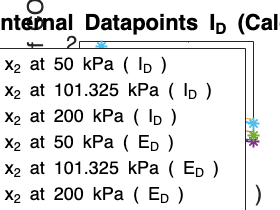


% The x-axes is altered so that degrees celcius is used (to stay true to 
% the specifics of question 2B).
figure
plot(T_K-273.15,x_2_I_D.*10^3,"-")
hold on
plot(Temperature_Degrees_Celcius',x_2_E_D,"--*",LineWidth=1)
xlabel("Temperature ( ^oC )")
ylabel("The Equilibrium Concentration of CO^2 in Water x_2 (ND)")
title("A Comparison of the Equilibrium Concentration of CO^2 in Wat" + ...
    "er x_2 Concerning Internal Datapoints I_D (Calculated in Appen" + ...
    "dix v) and External Datapoints E_D (Calculated in a Reference Article)")
legend('x_2 at 50 kPa ( I_D )','x_2 at 101.325 kPa ( I_D )',['x_2 at 2' ...
    '00 kPa ( I_D )'],'x_2 at 50 kPa ( E_D )',['x_2 at 101.325 kPa ( E' ...
    '_D )'],'x_2 at 200 kPa ( E_D )')









%EXTRA 2B:

% The for loop below calculates x_2 (& phi) for new values of Pressure
% in array P_B (values of phi change for different pressures).


% for s = 1:3
%     A = (a_star.*P_B(s))./((R.*T_K).^2)
%     B = (b.*P_B(s))./(R.*T_K)
%     % Z Peng-Robinson cubic coefficients (for CO2)
%     Zcoeff_co2(:,2) = -(1-B(:,1))
%     Zcoeff_co2(:,3) = A(:,1)-3.*B(:,1).^(2)-2.*B(:,1)
%     Zcoeff_co2(:,4) = -(A(:,1).*B(:,1)-B(:,1).^(2)-B(:,1).^(3))
%     % Z Peng-Robinson cubic coefficients (for water)
%     Zcoeff_water(:,2) = -(1-B(:,2))
%     Zcoeff_water(:,3) = A(:,2)-3.*B(:,2).^(2)-2.*B(:,2)
%     Zcoeff_water(:,4) = -(A(:,2).*B(:,2)-B(:,2).^(2)-B(:,2).^(3))
%     % Finding Real Positive Roots (for C02 and Water):
%     for e = 1:71
%         Zroots_co2 = roots(Zcoeff_co2(e,:));
%         Zroots_co2_real(e,:) = Zroots_co2(imag(Zroots_co2)==0)
%         Zroots_water = roots(Zcoeff_water(e,:));
%         Zroots_water_real(e,:) = Zroots_water(imag(Zroots_water)==0)
%     end
%     % Calculating phi_v for CO2:
%     phi_v_co2 = exp(Zroots_co2_real-1-log(Zroots_co2_real-B ...
%     (:,1))-(A(:,1)./(B(:,1).*2.*sqrt(2))).*log((Zroots_co2_real+(1+ ...
%     sqrt(2)).*B(:,1))./(Zroots_co2_real+(1-sqrt(2)).*B(:,1))))
%     % Calculating phi_l and phi_v for Water:
%     phi_l_water = exp(Zroots_water_real(:,3)-1-log(Zroots_water_real(:,3)...
%     -B(:,2))-(A(:,2)./(B(:,2).*2.*sqrt(2))).*log((Zroots_water_real(:,3)...
%     +(1+sqrt(2)).*B(:,2))./(Zroots_water_real(:,3)+(1-sqrt(2)).*B(:,2))))
%     phi_v_water = exp(Zroots_water_real(:,1)-1-log(Zroots_water_real(:,1)...
%     -B(:,2))-(A(:,2)./(B(:,2).*2.*sqrt(2))).*log((Zroots_water_real(:,1)...
%     +(1+sqrt(2)).*B(:,2))./(Zroots_water_real(:,1)+(1-sqrt(2)).*B(:,2))))
%     % Calculating phi_1 and phi_2:
%     phi_1(:,s) = phi_v_water./phi_l_water
%     phi_2(:,s) = phi_v_co2
% end


### Task 2C


% TASK 2C

% clear

% Below, MATLAB’s Import Data Function is Used to Transform the Data
% into a Manipulable Array:


**Transforming Table Data**

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["site_code", "measurement_id", "TIME", "TEMP", "Press_ATM", "CO2EQ_PPM"];
opts.VariableTypes = ["categorical", "double", "string", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "TIME", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["site_code", "TIME"], "EmptyFieldRule", "auto");

% Import the data
Project_Data = readtable("/Users/samanthadufumulleruri/Documents/UCL/YEAR 1/ENGF0003 - Mathematical Modelling and Analysis/Assessments/2 MATLAB COURSEWORK 2/DATA/Project_Data (1).csv", opts);

% Clear temporary variables
clear opts

% Display results
Project_Data

Project_Data = 172200×6 table
    site_code    measurement_id             TIME              TEMP     Press_ATM    CO2EQ_PPM
    _________    ______________    ______________________    ______    _________    _________

     NRSMAI          12943         "2020-05-22T06:00:00Z"    13.513      101.8       387.35  
     NRSMAI          12944         "2020-05-22T08:00:00Z"    13.554     101.84       385.32  
     NRSMAI          12945         "2020-05-22T10:00:00Z"    13.585     101.87       385.27  
     NRSMAI          12946         "2020-05-22T12:00:00Z"    13.571     101.86       384.79  
     NRSMAI          12947         "2020-05-22T14:00:00Z"      13.5     101.81       385.32  
     NRSMAI          12948         "2020-05-22T16:00:00Z"    13.455     101.72       384.53  
     NRSMAI  


% In the dataset CO2EQ_PPM (parts per million) is the value of y2 (the air
% concentration of CO2) while Press_ATM is Pressure (Pa).
% Additionally, all variables are expressed in their standard units.

% Below, Data Points From the Table Above (Project_Data) are Converted
% into Arrays:

% The code below isolates only the data rom the Great Barrier Reef.
project = Project_Data(Project_Data.site_code == "GBRWIS",:);

% Fill Missing Data:
project = fillmissing(project,"previous")

project = 59943×6 table
    site_code    measurement_id             TIME              TEMP     Press_ATM    CO2EQ_PPM
    _________    ______________    ______________________    ______    _________    _________

     GBRWIS          64494         "2020-03-06T08:00:00Z"    28.311     100.54       515.91  
     GBRWIS          64495         "2020-03-06T10:00:00Z"    28.492     100.66       497.84  
     GBRWIS          64496         "2020-03-06T12:00:00Z"    28.431      100.7       518.11  
     GBRWIS          64497         "2020-03-06T14:00:00Z"    28.394     100.66       488.41  
     GBRWIS          64498         "2020-03-06T16:00:00Z"    28.388     100.52       513.25  
     GBRWIS          64499         "2020-03-06T18:00:00Z"    28.367     100.52       525.28  
     GBRWIS        


% Convert from kPa (which are the units of pressure used in the column of 
% values: 'Press_ATM') to Pa (also convert temperature to Kelvin)).
pressure = (project.Press_ATM).*10^3;
temperature = (project.TEMP)+273.15;
y_2 = project.CO2EQ_PPM;

% Defining an Array for the Incompatible Datetime Values in the Raw Data:
time0 = sortrows(project.TIME);
time = datetime((time0), 'InputFormat','yyyy-MM-dd''T''HH:mm:ss''Z',...
    'TimeZone','UTC');

% The function file (Task2_Function_Values) from task 2A (appendix iv) is
% used to calculate H_21, phi_1 & phi_2 as below.

[H_21_2c, ~, ~, phi_2_2c] = Task2_Function_Values(pressure,temperature);

Tc =   304.1800  647.0960


Pc =      7380000    22064000


wh_af =     0.2250    0.3480


h1 = -6.8346

h2 = 12817

h3 = -3766800

h4 = 299700000

a1 = -7.8595

a2 = 1.8441

a3 = -11.7866

a4 = 22.6807

a5 = -15.9619

a6 = 1.8012

R = 8.3140

a =     0.3962    0.5998


a_star =     0.3988    0.9811
    0.3986    0.9808
    0.3987    0.9809
    0.3987    0.9810
    0.3987    0.9810
    0.3987    0.9810
    0.3986    0.9809
    0.3987    0.9810
    0.3986    0.9809
    0.3973    0.9788


b = 1×2
1.0e-04 *

    0.2666    0.1897


A = 59943×2
    0.0064    0.0157
    0.0064    0.0157
    0.0064    0.0157
    0.0064    0.0157
    0.0064    0.0157
    0.0064    0.0157
    0.0064    0.0157
    0.0064    0.0157
    0.0064    0.0157
    0.0063    0.0155


B = 59943×2
    0.0011    0.0008
    0.0011    0.0008
    0.0011    0.0008
    0.0011    0.0008
    0.0011    0.0008
    0.0011    0.0008
    0.0011    0.0008
    0.0011    0.0008
    0.0011    0.0008
    0.0011    0.0008



% Equation below is taken from equation 1.2 seen in the essay above (1)
% where x_2*H_21 = y_2*phi_2*pressure.
x_2_q2c = (y_2.*phi_2_2c.*pressure)./H_21_2c;

figure
% Cleaning Outliers (0.4 is a sensible replacement value for the outlier)
x_2_q2c(x_2_q2c>0.75) = 0.4

x_2_q2c = 59943×1
    0.2926
    0.2814
    0.2934
    0.2767
    0.2905
    0.2974
    0.2847
    0.2917
    0.2810
    0.2247


plot(time,x_2_q2c)
xlabel("Time (years)")
ylabel("Mass Fraction of CO_2 Dissolved in Water, x_2 (ppm?)")
title("Figure 9. Graph of x_2 Against Time")

% The 4x4 grid of graphs below are plots of y_2, phi_2, H_21 & pressure 
% against time for a comprhensive analytical evaluation of relevent data
% trends.
hold off
figure
subplot(2,2,1)
% Cleaning Outliers (709 is a sensible replacement value for the outlier)
% y_2(y_2>1200) = 709
plot(time,y_2)
xlabel("Time (years)")
ylabel("Mass Fraction of CO_2 in Gas Form, y_2 (ppm)")
title("Figure 10. Graph of y_2 Against Time")

hold on
subplot(2,2,2)
% Cleaning Outliers (0.99 is a sensible replacement value for the outlier)
phi_2_2c(phi_2_2c>0.995) = 0.994472

phi_2_2c = 59943×1
    0.9947
    0.9947
    0.9947
    0.9947
    0.9947
    0.9947
    0.9947
    0.9947
    0.9947
    0.9948


plot(time,phi_2_2c)
xlabel("Time (years)")
ylabel("Fugacity in the Vapour Phase of C0_2, phi_2 (ND?)")
title("Figure ??. Graph of phi_2 Against Time")

subplot(2,2,3)
% Cleaning Outliers (160121000 is a sensible replacement value for the
% outlier)
H_21_2c(H_21_2c>2*10^8) = 160121000

H_21_2c = 59943×1
1.0e+08 *

    1.7634
    1.7715
    1.7687
    1.7671
    1.7668
    1.7659
    1.7701
    1.7675
    1.7699
    1.8322


plot(time,H_21_2c)
xlabel("Time (years)")
ylabel("Temperature Dependent Henry’s Constant, H_21 (ND?)")
title("Figure ??. Graph of H_2_1 Against Time")

subplot(2,2,4)
plot(time,pressure)
xlabel("Time (years)")
ylabel("Pressure (Pa)")
title("Figure ??. Graph of Pressure Against Time")

figure
plot(time,temperature)

% EXTRA 2C
% time = sortrows(time)

% figure
% plot(time,temperature)

% Changing Title Font:
% title(titletext, 'FontSize', 15, 'FontNme')
